clf;
clear;

caster = imread("../images/caster_stand.tif");
[M,N,~] = size(caster)

M = 968

N = 968

subplot(1,2,1);
imshow(caster);title('Origin');

% gray image
caster = im2gray(caster);

% caculate the distribution
count = imhist(caster);
p = count/(M*N);
cdf = cumsum(p);
cdf_T = cumsum(p.*(1:256)');

% get the level
sigma = (cdf*cdf_T(end)-cdf_T).^2./(cdf.*(1-cdf));
[~,level] = max(sigma);
level = (level-1)/255

level = 0.3412

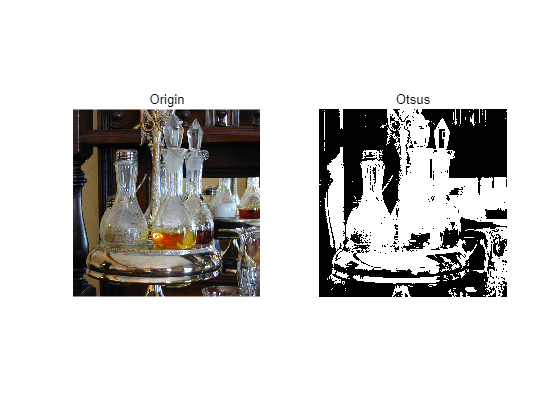


caster_Otsus = imbinarize(caster,level);

subplot(1,2,2);
imshow(caster_Otsus);title('Otsus');